load("./Data/Data1_H.mat");
load("./Data/Data1_V.mat");
load("./Data/Data2_W.mat");

## MP推导项与误差关系图

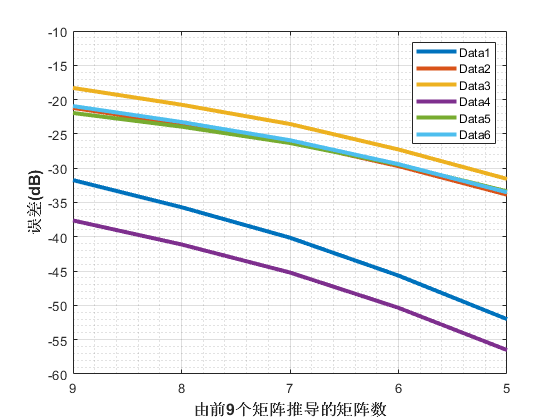


load('mp_test_result.mat');
plot(mp_test,'linewidth', 3)
grid on
grid minor
xticks([1 2 3 4 5]);
ylim([-60 -10])
legend('Data1','Data2','Data3','Data4','Data5','Data6');
xticklabels({'9', '8' ,'7' ,'6' ,'5'});
xlabel('由前9个矩阵推导的矩阵数','fontsize', 14,'FontWeight',"bold");
ylabel('误差(dB)','fontsize', 14,'FontWeight',"bold");

## 记忆项对NMSE的影响

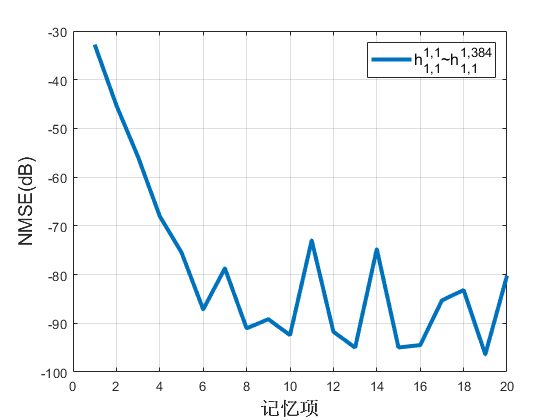



H1 = [];
H2 = [];
c_index = 1;
for i = 1:384-c_index
    H1 = cat(2,H1,(H(1,:,1,i)));
    H2 = cat(2,H2,(H(1,:,1,i+c_index)));
end

H3 = [];
H4 = [];
for i = 1:384-c_index
    H3 = [H3 H1((i-1)*64+1)];
    H4 = [H4 H2((i-1)*64+1)];
end

NMSE = [];
for i = 1:20
    [cc,n,yo,MM] = MP_e(H3(1:383),H4(1:383),1,i);
    NMSE = [NMSE n];
end

plot(NMSE,'linewidth', 3)
legend('h_{1,1}^{1,1}~h_{1,1}^{1,384}','fontsize',12);
grid on
xlabel('记忆项','fontsize', 14,'FontWeight',"bold");
ylabel('NMSE(dB)','fontsize', 14);

## 阶次对NMSE的影响

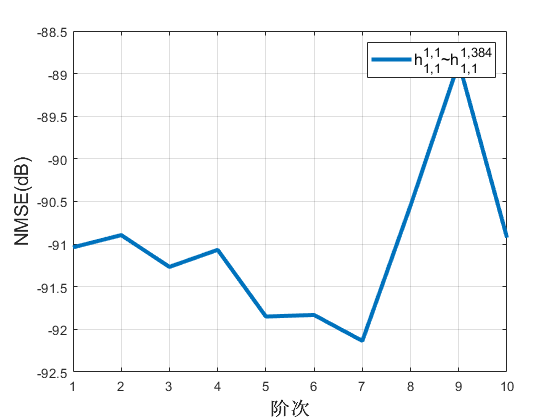

H1 = [];
H2 = [];
c_index = 1;
for i = 1:384-c_index
    H1 = cat(2,H1,(H(1,:,1,i)));
    H2 = cat(2,H2,(H(1,:,1,i+c_index)));
end

H3 = [];
H4 = [];
for i = 1:384-c_index
    H3 = [H3 H1((i-1)*64+1)];
    H4 = [H4 H2((i-1)*64+1)];
end

NMSE = [];
for i = 1:10
    [cc,n,yo,MM] = MP_e(H3(1:383),H4(1:383),i,8);
    NMSE = [NMSE n];
end

plot(NMSE,'linewidth', 3)
legend('h_{1,1}^{1,1}~h_{1,1}^{1,384}','fontsize',12);
grid on
xlabel('阶次','fontsize', 14,'FontWeight',"bold");
ylabel('NMSE(dB)','fontsize', 14);

## 矩阵内的关联性矩阵（幅度）

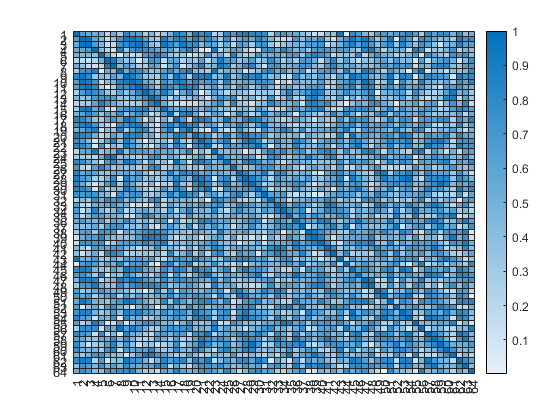

H1 = H(:,:,1,1);
w = heatmap(abs(corrcoef(H1)));

## 矩阵间关联性矩阵

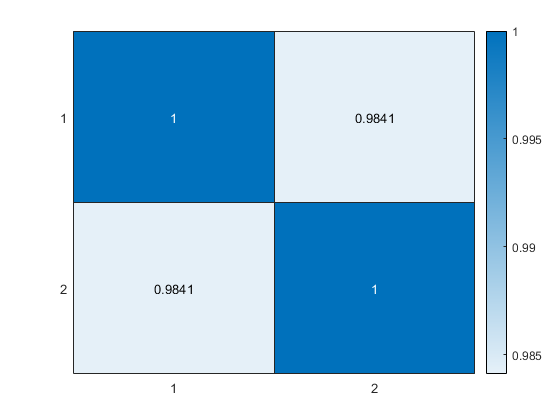

H1 = H(:,:,1,1);
H2 = H(:,:,1,2);
cof_abs = corrcoef(abs(H1),abs(H2));
cof_angle = corrcoef(angle(H1),angle(H2));
cof_real = corrcoef(real(H1),real(H2));
cof_image = corrcoef(imag(H1),imag(H2));

figure 
heatmap(cof_abs);

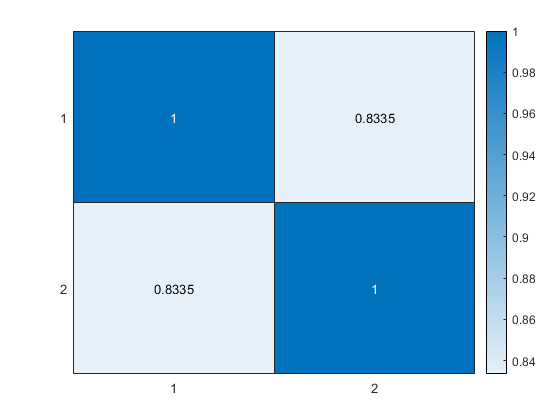


figure
heatmap(cof_angle);

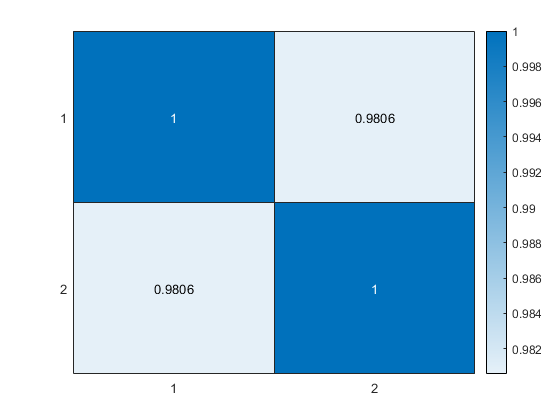

figure
heatmap(cof_real);

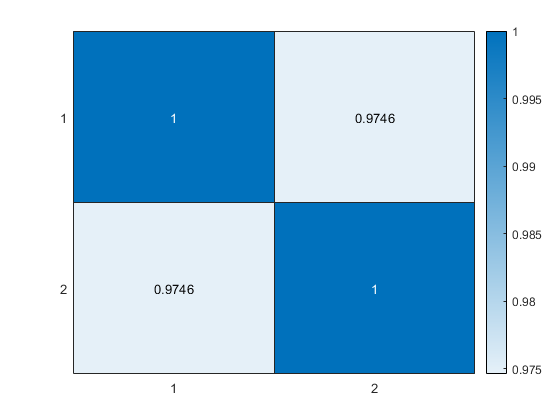


figure
heatmap(cof_image);

## 矩阵间行列的相关性

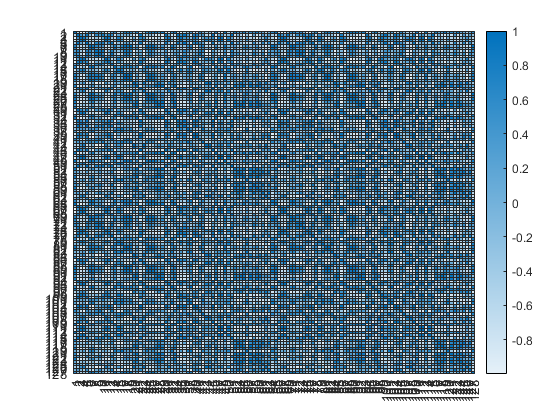

H1 = H(:,:,1,1);
H2 = H(:,:,1,2);

%列与列之间
H_temp = [H1 H2];
heatmap(corrcoef(abs(H_temp)));

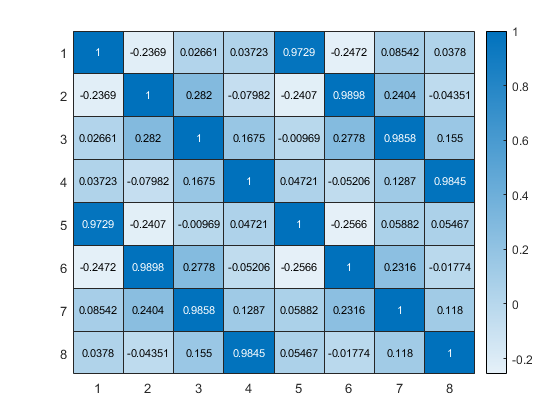



%行与行之间
figure
H1 = H1.';
H2 = H2.';
H_temp = [H1 H2];
heatmap(corrcoef(abs(H_temp)));

## W的左右关联度

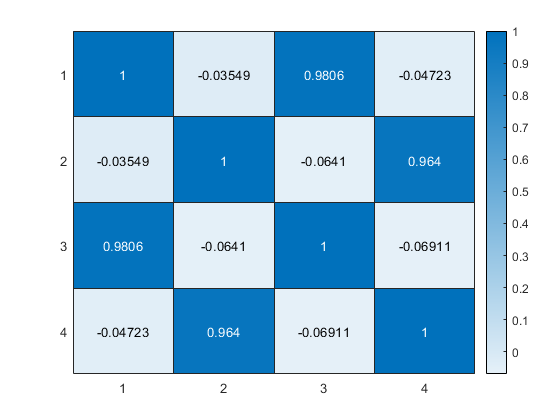

H1 = W(:,:,1,1);
H2 = W(:,:,1,2);

%列与列之间
H_temp = [H1 H2];
heatmap(corrcoef(abs(H_temp)));

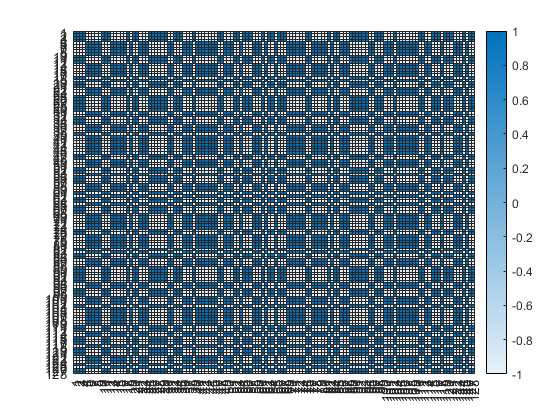



%行与行之间
figure
H1 = H1.';
H2 = H2.';
H_temp = [H1 H2];
heatmap(corrcoef(abs(H_temp)));

## W的上下关联度

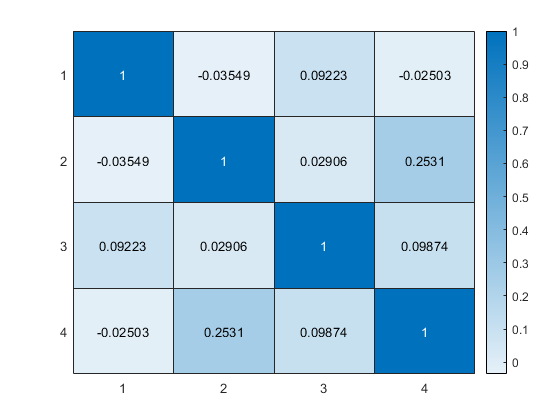

H1 = W(:,:,1,1);
H2 = W(:,:,2,1);

%列与列之间
H_temp = [H1 H2];
heatmap(corrcoef(abs(H_temp)));

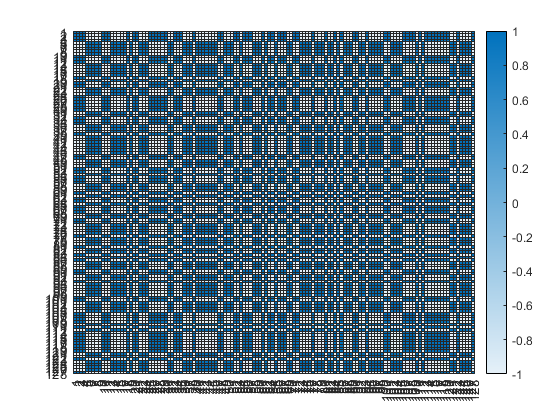



%行与行之间
figure
H1 = H1.';
H2 = H2.';
H_temp = [H1(:,1:64) H2(:,1:64)];
heatmap(corrcoef(abs(H_temp)));

## 数据的AM-AM与AM-PM关系

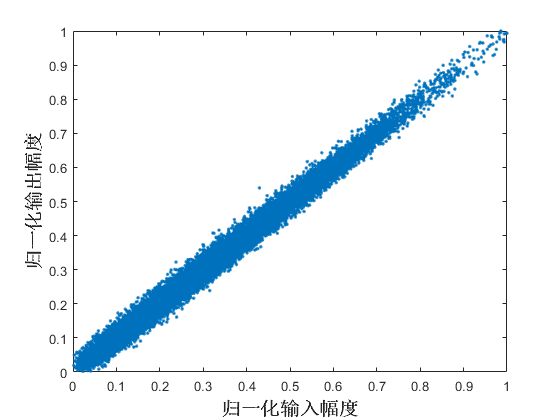

H1 = H(:,:,1,1);
H2 = H(:,:,1,2);
%做曲线拟合的
col1 = abs(H1(:,1));
col2 = abs(H2(:,1));


H1 = [];
H2 = [];
for i = 1:383
    H1 = cat(2,H1,(H(1,:,1,i)));
    H2 = cat(2,H2,(H(1,:,1,i+1)));
%     H1_abs = cat(2,H1_abs,abs(H(1,:,1,i)));
%     H2_abs = cat(2,H2_abs,abs(H(1,:,1,i+1)));
%     H1_angle = cat(2,H1_angle,angle(H(1,:,1,i)));
%     H2_angle = cat(2,H2_angle,angle(H(1,:,1,i+1)));
end

amam(H1,H2);
xlabel('归一化输入幅度','fontsize', 14,'FontWeight',"bold");
ylabel('归一化输出幅度','fontsize', 14,'FontWeight',"bold");

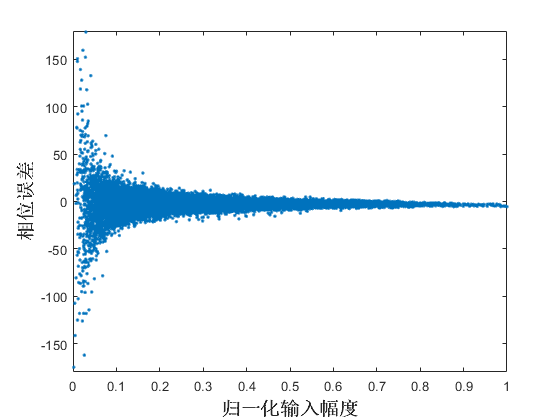


ampm(H1,H2);
xlabel('归一化输入幅度','fontsize', 14,'FontWeight',"bold");
ylabel('相位误差','fontsize', 14,'FontWeight',"bold");

## 数据分布图

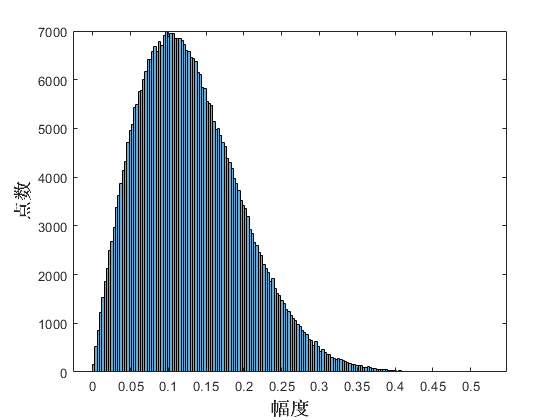

H1 = H(:,:,1,1);
H1_abs = abs(H1);
H_sum = [];
for i = 1:4
    for j = 1:384
        H_sum = [H_sum abs(H(:,:,i,j))]; 
    end
end
histogram(H_sum);
xlabel('幅度','fontsize', 14,'FontWeight',"bold");
ylabel('点数','fontsize', 14,'FontWeight',"bold");

H_sum = [];
for i = 1:4
    for j = 1:384
        H_sum = [H_sum angle(H(:,:,i,j))]; 
    end
end
histogram(H_sum);
xlabel('相位','fontsize', 14,'FontWeight',"bold");
ylabel('点数','fontsize', 14,'FontWeight',"bold");

## 单个MP系数用于多个元素的NMSE

H1 = [];
H2 = [];
c_index = 1;
for i = 1:384-c_index
    H1 = cat(2,H1,(H(1,:,4,i)));
    H2 = cat(2,H2,(H(1,:,4,i+c_index)));
end

H3 = [];
H4 = [];
for i = 1:383-c_index
    H3 = [H3 H1((i-1)*64+1)];
    H4 = [H4 H2((i-1)*64+1)];
end

[cc,n,yo,MM] = MP_e(H3(1:350),H4(1:350),2,8);
NMSE_YU(H4(28:350), yo(20:end))

ans = -91.8729

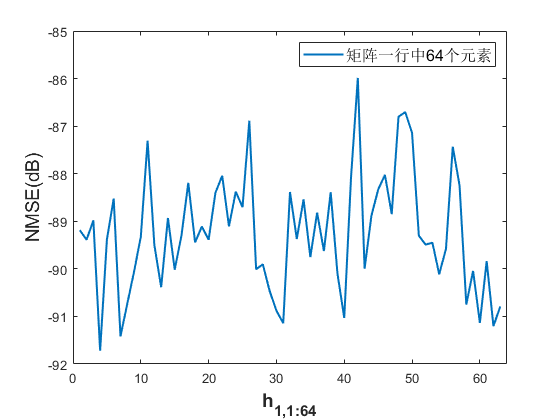

% yo = MP_v(H3(331:383-c_index),cc,2,7);
NMSE = [];
H5 = [];
H6 = [];

%单个元素标定用于一行64个元素
for j = 1:63
    for i = 1:383
        H5 = [H5 H1((i-1)*64+1+j) ];
        H6 = [H6 H2((i-1)*64+1+j)];
    end
    yo = MP_v(H5,cc,2,8);
    NMSE = [NMSE NMSE_YU(H6(10:end-10),yo(10:end-10))];
    H5 = [];
    H6 = [];
end
figure
plot(NMSE,'linewidth', 1.5)
legend('矩阵一行中64个元素','fontsize',12);
xlim([0 64])
% grid on
xlabel('h_{1,1:64}','fontsize', 14,'FontWeight',"bold");
ylabel('NMSE(dB)','fontsize', 14);

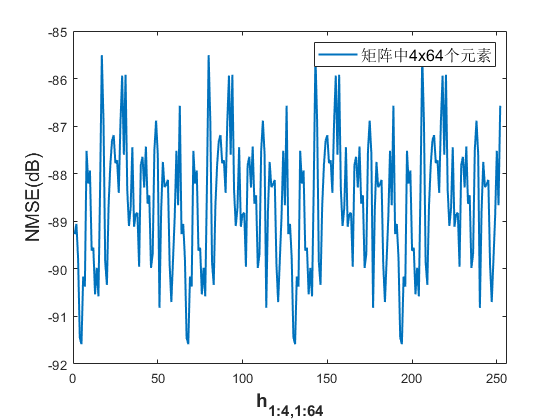

%单个元素系数标定其他所有元素

NMSE=[];
H7 = [];
H8 = [];
for j = 1:4
    for i = 1:383
        H7 = cat(2,H7,(H(j,:,1,i)));
        H8 = cat(2,H8,(H(j,:,1,i+1)));
    end
    
    H9 = [];
    H10 = [];
    for j = 1:63
        for i = 1:383
            H9 = [H9 H7((i-1)*64+1+j) ];
            H10 = [H10 H8((i-1)*64+1+j)];
        end
        yo = MP_v(H9,cc,2,8);
        % H10和yo并不是完全相等的，虽然amam和ampm都是条直线，但是每个值对yo都是H10的3.514倍，归一化导致
        NMSE = [NMSE NMSE_YU(H10(10:end-10),yo(10:end-10))];
        H9 = [];
        H10 = [];
    end
end

plot(NMSE,'linewidth', 1.5)
legend('矩阵中4x64个元素','fontsize',12);
xlim([0 256])
% grid on
ax = gca;
ax.grid = '--';
xlabel('h_{1:4,1:64}','fontsize', 14,'FontWeight',"bold");
ylabel('NMSE(dB)','fontsize', 14);